# Temperature-controlled water tank

**using on-off logical control modelled with the hybrid dmss class.**

[Open Live Script in Matlab](matlab:open('oneTankDemo.mlx'))

close all, clear

**Example for CoDIT 2024 Conference [1].**

## **Model creation**

The system describes a temperature-controlled water tank, as illustrated in figure 1. The tank loses heat to the ambient due to the temperature difference between the water temperature x1 of the tank and the ambient temperature u2. The water tank includes a hot water inlet with the temperature u1, which is used to control the water temperature x1.

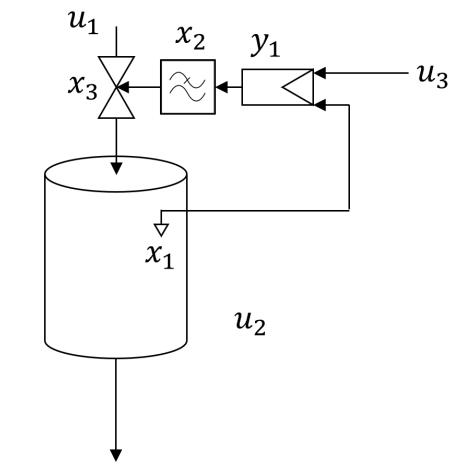

**Figure 1: Schematic diagram of the temperature-controlled water tank**

The inlet valve is regulated by a 1-point controller (on-off controller), producing a binary-valued signal z1 indicating whether the temperature is above or below the setpoint u3. To prevent Zeno-behavior, the controller output z1 undergoes a low-pass filter, resulting in the filtered signal x2. The filter signal x2 is then fed into the inert actuator valve, which controls the inlet flow rate based of its position value x3. 

The model can be described by the following set of dAEs


$$0 = m c_p x_1(k+1) + (k A T_s - m c_p) x_1(k) - k A T_s u_2(k) + c_p f_v T_s (x_1(k) x_3(k)-u_1(k) x_3(k)) \\
0 = (T_f T_s - 1) x_2(k) +x_2(k+1) + T_s (x_3(k)-z_1(k)) \\
0 = x_3(k+1)-x_3(k)- T_s x_2(k) \\
0 \ge  x_1(k) (2 z_1(k)-1)-u_3(k) (2 z_1(k)-1)$$


The implicit multilinear model can be described by the following hybrid CPn-1 tensor:

H = hyCPN1()

H =   hyCPN1 with properties:

      F: [1×1 struct]
    phi: [1×1 struct]



m = 5; %kg / 2kg
cp = 4200; %J/kgK
Ts = 0.1;
kA =  350* (0.5*1);
fv = 0.044;

H.F.stateDerivative = [1 0 0 0 0 0 0 0 0 0 0 0;...
    0 0 0 0 0 0 0 0 1 0 0 0;...
    0 0 0 0 0 1 0 0 0 0 0 0];
H.F.state = [0 1 0 1 0 0 0 0 0 0 1 0;...
    0 0 0 0 0 0 0 1 0 0 0 0;...
    0 0 0 1 1  0 1 0 0 0 0 0];
H.F.boolean = [0 0 0 0 0 0 0 0 0 1 2 2];
H.F.input = [0 0 0 0 1 0 0 0 0 0 0 0;...
    0 0 1 0 0 0 0 0 0 0 0 0;...
    0 0 0 0 0 0 0 0 0 0 0 1];

H.phi.equality = [m*cp (kA*Ts-m*cp) -kA*Ts cp*fv*Ts -cp*fv*Ts 0 0 0 0 0 0 0;...
    0 0 0 0 0 0 Ts (15*Ts-1) 1 -Ts 0 0;...
    0 0 0 0 0 1 -1 -Ts 0 0 0 0];
H.phi.inequality = [0 0 0 0 0 0 0 0 0 0 1 -1];

where H.F indicate the structure matrix and H.phi indicate the parameter matrix.

A dmss model can be created from this tensor

sys = dmss(H, Ts);

The according symbolic equations can be viewed to check the correctness of the model:

disp(sys.symbolicEquations)

$$\left(\begin{array}{c} 21000\,{\mathrm{xp}}_{1}-\frac{41965\,x_{1}}{2}-\frac{35\,u_{2}}{2}-\frac{462\,u_{1}\,x_{3}}{25}+\frac{462\,x_{1}\,x_{3}}{25}=0\\ \frac{x_{2}}{2}+\frac{x_{3}}{10}+{\mathrm{xp}}_{2}-\frac{z_{1}}{10}=0\\ {\mathrm{xp}}_{3}-x_{3}-\frac{x_{2}}{10}=0\\ x_{1}\,\left(2\,z_{1}-1\right)-u_{3}\,\left(2\,z_{1}-1\right)\leq 0 \end{array}\right)$$

The incidence matrix can be calculated by 

I = sys.incidenceMatrix;
I = [I.equality.stateDerivative, I.equality.algebraic, I.equality.boolean;...
    I.inequality.stateDerivative, I.inequality.algebraic, I.inequality.boolean];
disp(full(I))

     1     0     0     0
     0     1     0     1
     0     0     1     0
     0     0     0     1



and resorted using the Dulmage-Mendelsohn decomposition into a block lower triangular representation:

I = sys.orderIncidenceMatrix(I);
disp(full(I))

     1     0     0     0
     0     1     0     0
     1     0     1     0
     0     0     0     1



## Simulation

To simulate the system input signals and initial states must be defined:

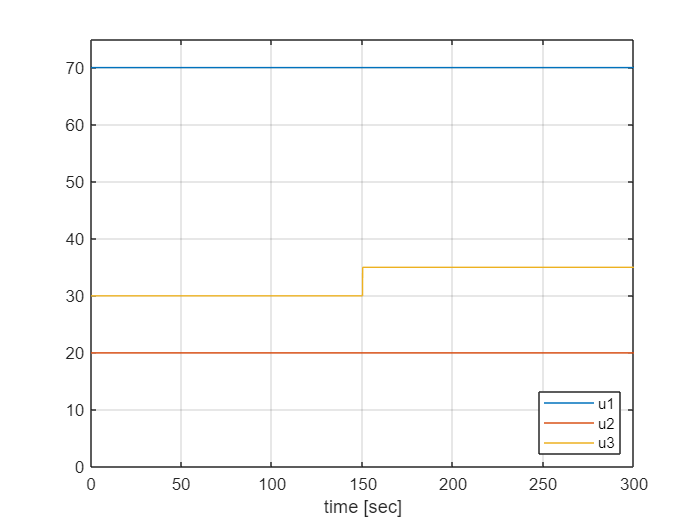

ut = 0:sys.ts:300;
x0 = [25; 0; 0];
u = [70, 20, 30] .* ones(size(ut))';
u(ut>150,3) = u(ut>150,3) + 5;

figure
plot(ut, u)
hold on
grid on
xlabel('time [sec]')
legend(["u1", "u2", "u3"],'location', 'southeast')
axis([0 300 0 75])
hold off

Now the system can be simulated using the dmsim simulation class, where on default reordering of equations is implemented using sparsity pattern analysis.

tic()
result = dmsim(sys, x0, ut, u);
time = toc()

time = 0.5122

Simulation can also be performed with the reordering algorithm and solving strategy turned off, but simulation time takes longer (especially for larger models), since in each timestep all variables of the inital value problem will be solved by an optimization algorithm:

opt.equationReordering = false;
tic()
resultOff = dmsim(sys, x0, ut, u, opt);
timeOff = toc()

timeOff = 16.3787

The simulation times per time step are:

disp(time/length(ut))

   1.7069e-04



disp(timeOff/length(ut))

    0.0055



The simulation results can be accessed via the properties of the simulation class and can be plotted:

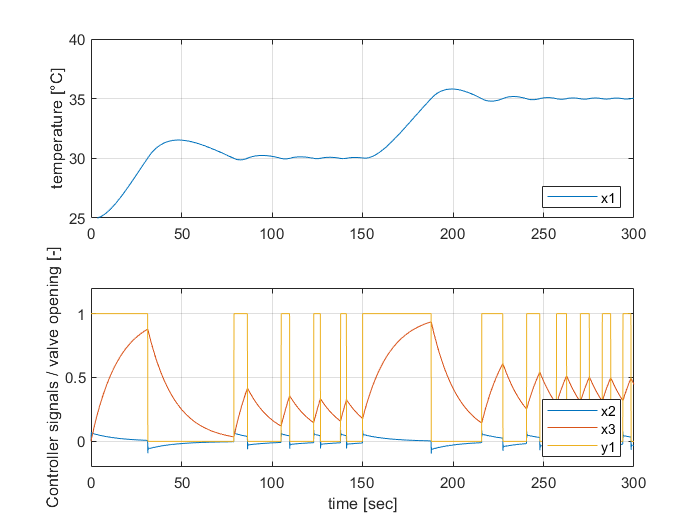

figure
subplot(2,1,1)
plot(result.tsim, [result.x(:,1)])
hold on
grid on
legend("x1", 'location', 'southeast')
ylabel('temperature [°C]')
axis([0 300 25 40])
hold off
subplot(2,1,2)
plot(result.tsim, [result.x(:,2:3), result.z])
hold on
grid on
ylabel('Controller signals / valve opening [-]')
xlabel('time [sec]')
legend(["x2", "x3", "y1"],'location', 'southeast')
axis([0 300 -0.2 1.2])
hold off

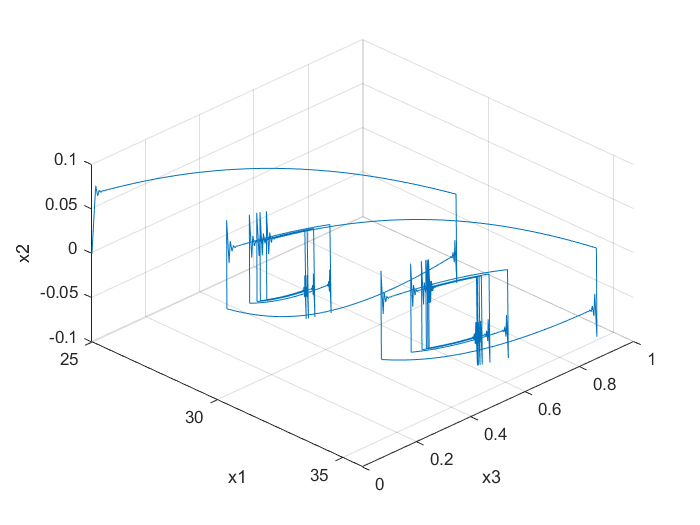


figure
plot3(result.x(:,1), result.x(:,3), result.x(:,2))
hold on
xlabel('x1')
ylabel('x3') 
zlabel('x2')
grid on
view([45 45])
hold off

## References

[1] T. Warnecke and G. Lichtenberg, "Hybrid implicit multilinear simulation using difference algebraic equations reordering by sparsity patterns", 2024 10th International Conference on Control, Decision and Information Technologies (CoDIT), Valletta, Malta, 2024. In press.

Author(s): Torben Warnecke